clearvars
d ='C:\Users\Level1Zach\Desktop\Testdata\';
sonde = 1;
% if using DFM-17 set sonde = 1
% if using RS92 set sonde = 2
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

if sonde == 2
t = fullfile(d, "*.csv");
files = dir(t);
else
t = fullfile(d, "*.txt");
files = dir(t);
end
i=1;
current = files(i).name;
current = fullfile(d, current);
if sonde == 2
    data = readRS92Data(current);
else
    data = readRadioSondeData(current);
end
%  [~, idx] = max(data.Alt);
% data = data(1:idx, :);
% data = data(data.Alt > 12000, :);
% if isempty(data)
%     warning("No data above 12000m");
% end
i=1

i = 1

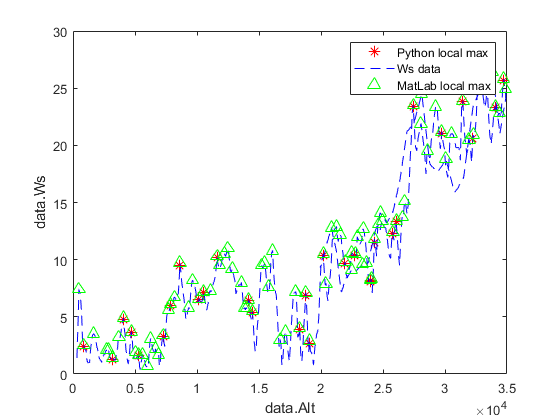

current = files(i).name;
current = fullfile(d, current);
if sonde == 2
    data = readRS92Data(current);
else
    data = readRadioSondeData(current);
end
%  [~, idx] = max(data.Alt);
% data = data(1:idx, :);
% data = data(data.Alt > 12000, :);
% if isempty(data)
%     warning("No data above 12000m");
% end
figure(4)
clf;
p = 0;
hi = data.Alt-data.Alt(1);
lmxt = [75, 465, 615, 715, 815, 1135, 1235, 1345, 1575, 1625, 1785, 2155, 2195, 2705, 2765, 2805, 2935, 3155, 3245, 3382, 3385, 3415, 3565, 3595, 3745, 3965, 4125, 4215, 4315, 4375, 4455];
lmxt2 = islocalmax(data.Ws,'MinProminence',p);
plot (data.Alt(lmxt),data.Ws(lmxt),'r*','MarkerSize',8)
hold on
plot (data.Alt,data.Ws,'b--')
lmx = find(lmxt2==1);
plot(data.Alt(lmx),data.Ws(lmx),'g^','MarkerSize',8)
legend('Python local max','Ws data','MatLab local max');
xlabel('data.Alt'); ylabel('data.Ws');

% lmx = lmxt;
%  for i = 1:length(lmx)
%     lmxx = lmx(end);
%     if lmx(i) <= (lmxx-400)
%         lmx_final(i) = lmx(i);
%     end
%  end
% 
% Ws_upper = data.Ws(lmx_final+400);
% Ws_lower = data.Ws(lmx_final);
% Ws_math = Ws_upper-Ws_lower;
% k = 1;
% for i = 1:length(lmx_final)
%     j = lmx_final(i);
%     if abs(data.Ws(j)) >= 7.5
%         hi_final(k) = hi(j);
%         k=k+1;
%     end
% end
% hi_max = hi_final;

% lmxt = [315, 1025, 115, 1295, 1454, 1805, 2005, 2115, 2595, 2663, 2685, 2795, 3383, 3395, 3435, 3465, 3545, 3625, 3775, 3845, 3955, 4105, 4205, 4295, 4345, 4474];
% lmxt =  islocalmin(data.Ws,'MinProminence',p);
% lmx = find(lmxt==1);
% lmx = lmxt;
% for i = 1:length(lmx)
%     lmxx = lmx(end);
%     if lmx(i) <= (lmxx-400)
%         lmx_final(i) = lmx(i);
%     end
% end
% 
% Ws_upper = data.Ws(lmx_final+400);
% Ws_lower = data.Ws(lmx_final);
% Ws_math = Ws_upper-Ws_lower;
% k = 1;
% for i = 1:length(lmx_final)
%     j = lmx_final(i);
%     if abs(data.Ws(j)) >= 7.5
%         hi_final(k) = hi(j);
%         k=k+1;
%     end
% end
% hi_min = hi_final
% hi_final = [hi_max;hi_min]